# ENAE432 - Homework 7

Vai Srivastava

% Clear history
clear;
clc;

## Problem 1

s = tf('s');

k_1 = 1;
k_2 = 2;

num_1 = 7*k_1;
num_2 = 7*k_2;

denom = (s/5+1)^3;

L_1 = num_1/denom


L_1 =
 
             875
  -------------------------
  s^3 + 15 s^2 + 75 s + 125
 
Continuous-time transfer function.
Model Properties


L_2 = num_2/denom


L_2 =
 
            1750
  -------------------------
  s^3 + 15 s^2 + 75 s + 125
 
Continuous-time transfer function.
Model Properties


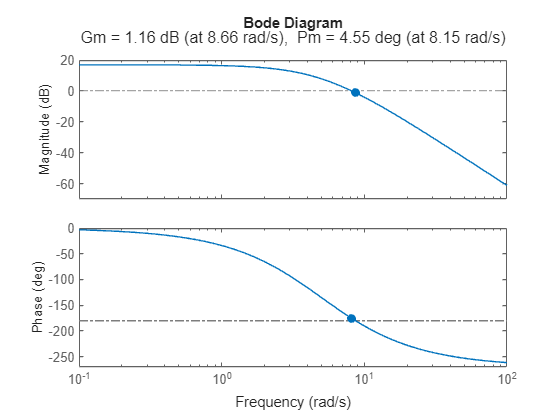


margin(L_1)

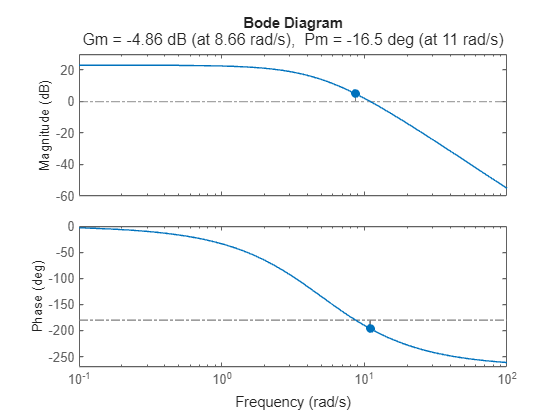

margin(L_2)


10^(-1.16/20)

ans = 0.8750

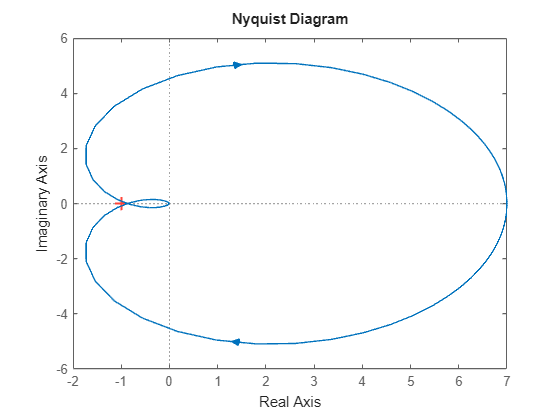


nyquist(L_1)

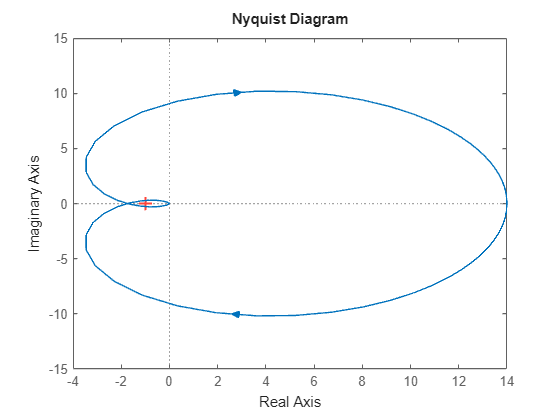

nyquist(L_2)


L = 7*0.3438/(s/5+1)^3


L =
 
            300.8
  -------------------------
  s^3 + 15 s^2 + 75 s + 125
 
Continuous-time transfer function.
Model Properties


T = L/(1+L)


T =
 
                300.8 s^3 + 4512 s^2 + 2.256e04 s + 3.76e04
  ------------------------------------------------------------------------
  s^6 + 30 s^5 + 375 s^4 + 2801 s^3 + 1.389e04 s^2 + 4.131e04 s + 5.323e04
 
Continuous-time transfer function.
Model Properties


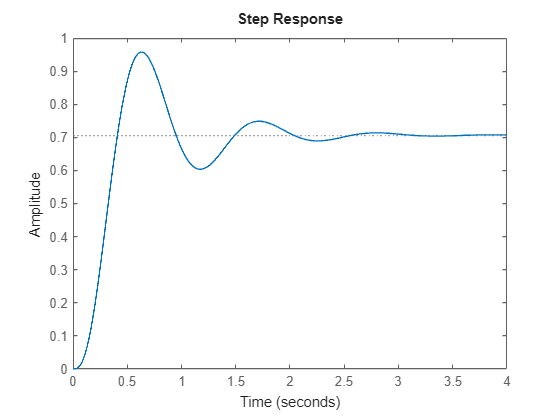

step(T)


U = 0.3438*(1-T)/s


U =
 
   0.3438 s^6 + 10.31 s^5 + 128.9 s^4 + 859.5 s^3 + 3223 s^2 + 6446 s + 5372
  ----------------------------------------------------------------------------
  s^7 + 30 s^6 + 375 s^5 + 2801 s^4 + 1.389e04 s^3 + 4.131e04 s^2 + 5.323e04 s
 
Continuous-time transfer function.
Model Properties



K = 0.3438

K = 0.3438

G = 7/((s/5 + 1)^3);
T = feedback(G*K, 1)


T =
 
             300.8
  ---------------------------
  s^3 + 15 s^2 + 75 s + 425.8
 
Continuous-time transfer function.
Model Properties


step(T)

## Problem 3

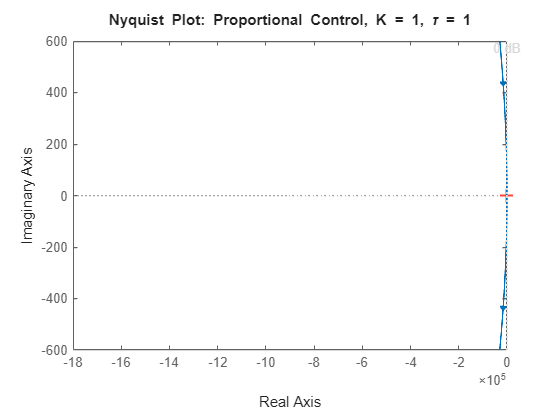

%% Hovercraft Control Analysis using Nyquist and Step Response Plots
% This script analyzes a hovercraft system modeled by
%     G(s) = 12/(s^2*(tau*s+1))
% and examines control using (a) proportional control and (b) PD control.
% Parts (c)-(e) include searching for the optimal PD gains (with tau=0.17),
% computing closed-loop poles, and comparing step responses.

%% Part (a): Proportional Control
% With proportional control u(t) = K e(t), the open-loop transfer function is:
%     L(s) = K*G(s) = 12*K/(s^2*(tau*s+1))
% We will generate the Nyquist plot to show that for any positive K,
% the system cannot be stabilized.
%
% For illustration, choose a sample tau (say, tau = 1) and K = 1.
tau = 1;       % Example time constant for demonstration
K_prop = 1;    % Proportional gain

s = tf('s');
G = 12/(s^2*(tau*s+1));
L_prop = K_prop * G;

figure;
nyquist(L_prop);
title('Nyquist Plot: Proportional Control, K = 1, \tau = 1');
grid on;

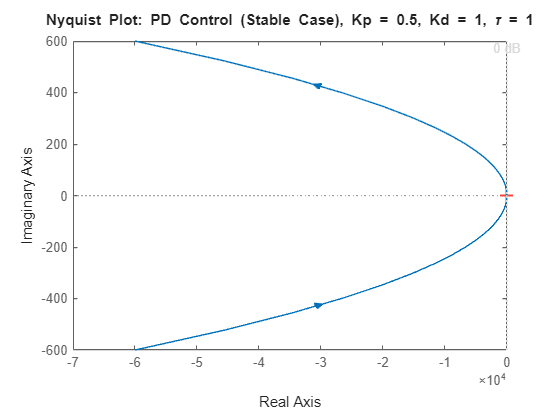

% The Nyquist plot shows that the -1 point is encircled regardless of gain,
% implying that a simple proportional controller cannot stabilize the system.

%% Part (b): PD Control
% Now consider the PD controller: 
%     u(t) = Kp*e(t) + Kd*de/dt,  so that C(s) = Kp + Kd*s.
%
% The open-loop transfer function becomes:
%     L_PD(s) = (Kp + Kd*s)*G(s)
% It can be shown that the closed-loop system is stable provided that:
%     tau*Kp < Kd.
%
% We generate two Nyquist plots: one for a set of gains satisfying tau*Kp < Kd,
% and one for gains that violate this inequality.
%
% Case 1: Stable PD gains (choose tau = 1, Kp = 0.5, Kd = 1, so 1*0.5 < 1)
Kp_stable = 0.5;
Kd_stable = 1;
L_PD_stable = (Kp_stable + Kd_stable*s)*G;

figure;
nyquist(L_PD_stable);
title('Nyquist Plot: PD Control (Stable Case), Kp = 0.5, Kd = 1, \tau = 1');
grid on;

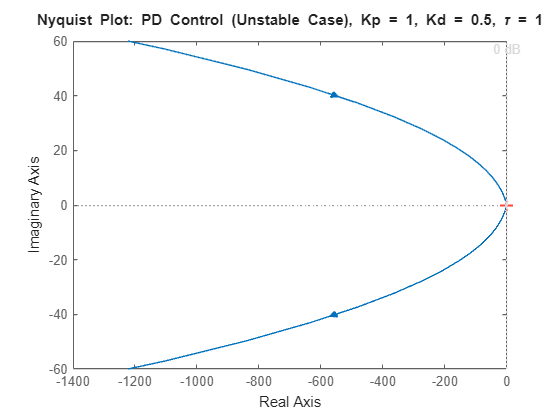


% Case 2: Unstable PD gains (choose Kp = 1, Kd = 0.5, so 1*1 > 0.5)
Kp_unstable = 1;
Kd_unstable = 0.5;
L_PD_unstable = (Kp_unstable + Kd_unstable*s)*G;

figure;
nyquist(L_PD_unstable);
title('Nyquist Plot: PD Control (Unstable Case), Kp = 1, Kd = 0.5, \tau = 1');
grid on;

% Note: Compare the location of the zero in L_PD(s) relative to the pole at -1/tau.

%% Part (c): Optimal PD Gains for Maximum Phase Margin (tau = 0.17, Kd = Kp)
% Now set tau = 0.17 and assume Kd = Kp.
% Our open-loop transfer function becomes:
%     L_PD(s) = 12*Kp*(1+s)/(s^2*(0.17*s+1)).
%
% We search over a range of Kp values to find the one that maximizes the phase margin.
tau = 0.17;  % Updated tau for part (c)
Kp_vals = logspace(-2, 3, 500);  % Sweep Kp from 0.01 to 1000
phaseMargins = zeros(size(Kp_vals));

for i = 1:length(Kp_vals)
    L_PD = 12*Kp_vals(i)*(1+s)/(s^2*(tau*s+1));
    [~, Pm, ~, ~] = margin(L_PD);
    phaseMargins(i) = Pm;
end

[maxPm, idx] = max(phaseMargins);
Kp_opt = Kp_vals(idx);
Kd_opt = Kp_opt;  % since Kd = Kp

fprintf('Optimal Kp (and Kd) for maximal phase margin: %f\n', Kp_opt);

Optimal Kp (and Kd) for maximal phase margin: 0.200727


fprintf('Maximum Phase Margin = %f deg\n', maxPm);

Maximum Phase Margin = 45.185850 deg


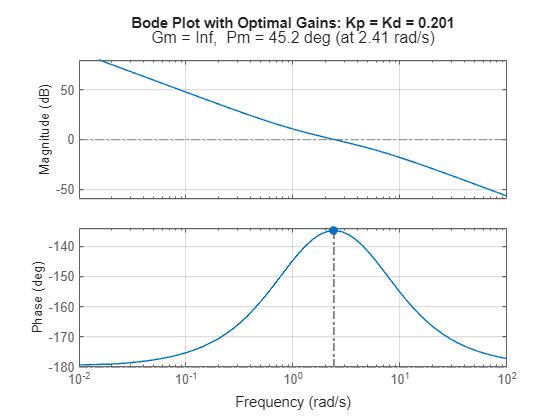


% Plot Bode plot with margins for the optimal gain
L_PD_opt = 12*Kp_opt*(1+s)/(s^2*(tau*s+1));
figure;
margin(L_PD_opt);
title(sprintf('Bode Plot with Optimal Gains: Kp = Kd = %.3f', Kp_opt));
grid on;


% Determine the closed-loop poles:
T = feedback(L_PD_opt, 1);
poles = pole(T);
disp('Closed-loop poles for the optimal PD gains:');

Closed-loop poles for the optimal PD gains:


disp(poles);

  -2.4671 + 0.0000i
  -1.7076 + 1.6814i
  -1.7076 - 1.6814i



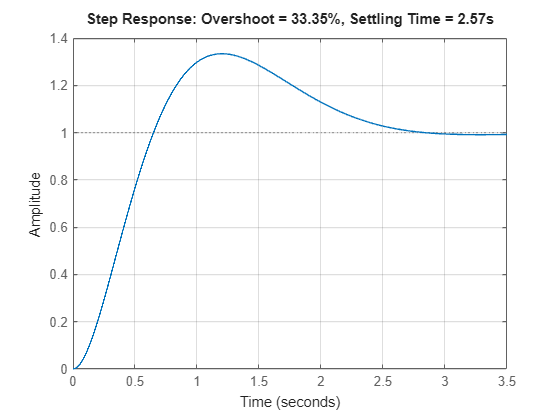

% All poles should lie in the left half-plane, confirming stability.

%% Part (d): Step Response Analysis
% For a unit step reference y_d(t), simulate the closed-loop response:
figure;
step(T);
info = stepinfo(T);
title(sprintf('Step Response: Overshoot = %.2f%%, Settling Time = %.2fs', info.Overshoot, info.SettlingTime));
grid on;

%
% Based on the pole locations of T(s), you might predict a modest overshoot.
% However, the step response shows more overshoot than predicted. This is
% typically because non-minimum phase characteristics (or lightly damped complex poles)
% lead to additional transient peaks that are not captured by a simple dominant pole analysis.

%% Part (e): Increasing Phase Margin by 10 Degrees
% Suppose we wish to increase the phase margin by 10°.
% One effective strategy is to modify the controller gains so that the zero of 
% C(s)=Kp+Kd*s is shifted left relative to the pole at -1/tau. In practice, 
% this means increasing the derivative gain relative to the proportional gain
% (i.e., choosing Kd > Kp) while still ensuring tau*Kp < Kd.
%
% For demonstration, let us keep Kp = Kp_opt (from part c) and choose:
beta = 1.5;    % Increase the derivative gain by a factor beta (>1)
Kp_new = Kp_opt;
Kd_new = beta * Kp_new;
L_PD_new = 12*(Kp_new + Kd_new*s)/(s^2*(tau*s+1));

% Compute the new phase margin:
[~, Pm_new, ~, ~] = margin(L_PD_new);
fprintf('New phase margin with modified gains (Kp = %.3f, Kd = %.3f): %f deg\n', Kp_new, Kd_new, Pm_new);

New phase margin with modified gains (Kp = 0.201, Kd = 0.301): 49.555003 deg



% Compare the magnitude crossover frequencies:
[~, ~, Wcg_opt, ~] = margin(L_PD_opt);
[~, ~, Wcg_new, ~] = margin(L_PD_new);
fprintf('Old magnitude crossover frequency: %f rad/s\n', Wcg_opt);

Old magnitude crossover frequency: 0.000000 rad/s


fprintf('New magnitude crossover frequency: %f rad/s\n', Wcg_new);

New magnitude crossover frequency: 0.000000 rad/s


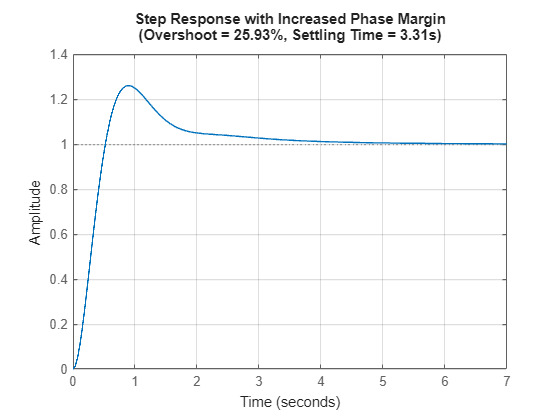

% Typically, increasing the phase margin (by increasing derivative action)
% reduces the crossover frequency, which may lead to slower closed-loop dynamics.

% Obtain the new closed-loop step response and compare transients:
T_new = feedback(L_PD_new, 1);
figure;
step(T_new);
info_new = stepinfo(T_new);
title(sprintf(['Step Response with Increased Phase Margin\n',...
    '(Overshoot = %.2f%%, Settling Time = %.2fs)'], info_new.Overshoot, info_new.SettlingTime));
grid on;

%
% Quantitatively, you will observe that the increased derivative gain (and hence increased phase margin)
% results in a lower crossover frequency, meaning that while the system becomes more robust,
% the transient response is slower (longer settling time) and the overshoot characteristics change.
%
% In summary, to gain an extra 10° of phase margin you can increase Kd relative to Kp.
% This redesign decreases the magnitude crossover frequency and leads to a more sluggish step response.

%% End of Script
